Name: **Michal Szabo**

Date:** 12.11.2021**

# **First Exercise**

## **Exercise 1**

The Laplacian of a Gaussian h, (LoG) is:


$$\nabla^2 h\left(r\right)=-\left\lbrack \frac{r^2 -\sigma^2 }{\sigma^4 }\right\rbrack e^{\frac{r^2 }{2\sigma^2 }}$$


where $r^2 =x^2 +y^2$ and $\sigma$ is the standard deviation.

**Questions:**

- **1. Why the result of applying the filter LoG and after the zero crossing, always returns closed contours?**

Because we can imagine that the zero crossing is doing the same like equal-elevation lines on topo map, that are also closed contours because there is no rapid change in height. The zero-crossing is showing us contours at hight zero which is after Gaussian filter that will blurry the image, so we will have small change in the graylevel intensity and the Laplacian that will create an image with negative and positive values.

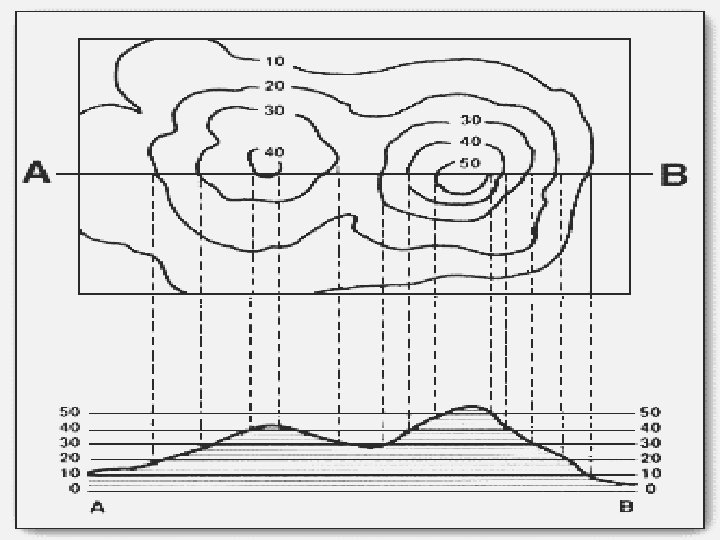

- **2. Explain why the Sobel filter obtains wider contours than the zero crossing filter.**

Because sobel filter is a small 3x3 matrix mask that is calculating the difference between pixels. In the image we can have not very sharp edges, where the change of the graylevel intesity is small but there still is a change, so the edge will be a wide line. Where in zero crossing we can get also one pixel line where there is only one pixel with graylevel equaled to 0.

- **3. Let us compare two different methods over the same image. The first one is to apply only the LoG filter; the second one is to apply a            median filter and after the Laplacian. Have the two methods the same result? Reason the answer of this question.**

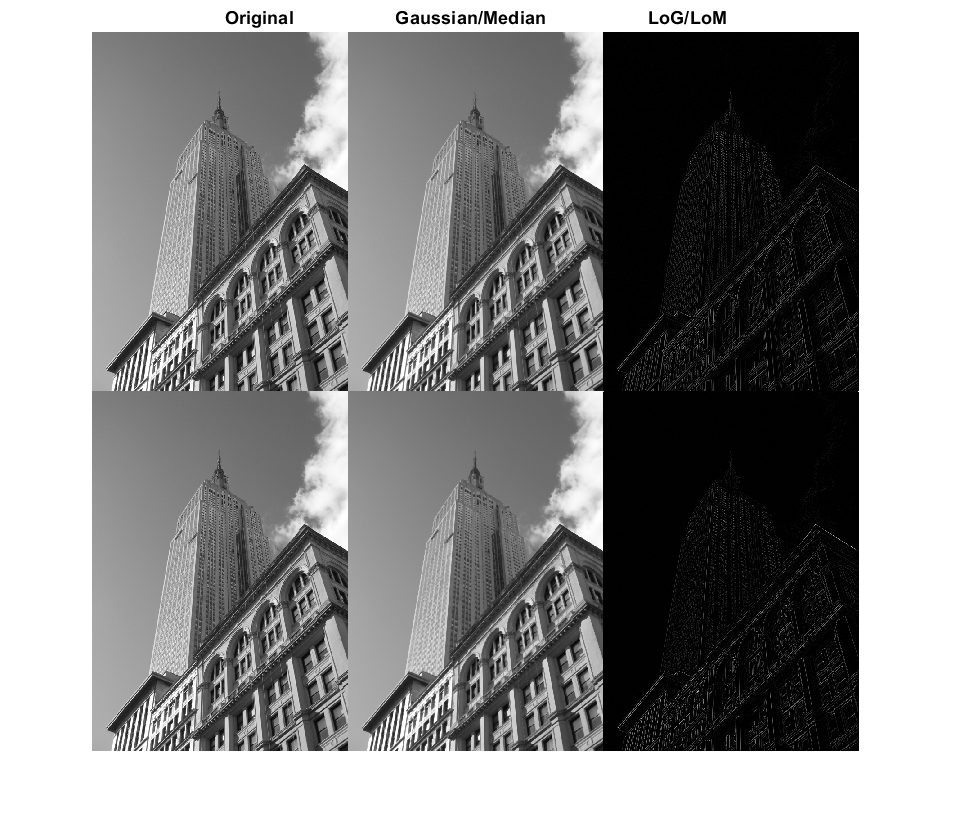

I = imread('images\building2.jpg');
gray_I = rgb2gray(I);

Gaussian = fspecial('gaussian',3,0.5);
I_Gauss = imfilter(gray_I,Gaussian);

I_Med = medfilt2(gray_I,[3 3]);

Laplacian = fspecial('laplacian',0.2);
I_LoG = imfilter(I_Gauss,Laplacian);
I_LoM = imfilter(I_Med,Laplacian);

figure
montage({gray_I,I_Gauss,I_LoG,gray_I,I_Med,I_LoM},'Size',[2 3])
title('Original                    Gaussian/Median                    LoG/LoM')

No. Not the same but very similar. What they are both doing si blurrying the image but using different techniques. 

Gaussian filter is a linear type of filter based on Gaussian function, that gives more value to the pixels closer to the center of the mask. We can imagine mask for example like this:

$G=\left\lbrack \begin{array}{ccc}
1 & 2 & 1\\
2 & 4 & 2\\
1 & 2 & 1
\end{array}\right\rbrack$    $\textrm{Image}=\left\lbrack \begin{array}{ccc}
50 & 50 & 100\\
50 & 50 & 100\\
50 & 50 & 100
\end{array}\right\rbrack$         Calculated matrix $=\left\lbrack \begin{array}{ccc}
50 & 100 & 100\\
100 & 200 & 200\\
50 & 100 & 100
\end{array}\right\rbrack =1000$     pixel value $=\frac{1000}{16}=62,5\;$

So we multiply pixels by the mask, then sum all the values and divide them by sum of the mask (In our example 16) and we get the value for the pixel in the middle.

On the other hand median filter is a non-linear type of filter, where we just take all the values under the mask, order them from min to max and take the middle one (median). This way we did not calculate a new pixel value we just assign the median value to the middle pixel.

$G=\left\lbrack \begin{array}{ccc}
1 & 1 & 1\\
1 & 1 & 1\\
1 & 1 & 1
\end{array}\right\rbrack$    $\textrm{Image}=\left\lbrack \begin{array}{ccc}
50 & 50 & 100\\
50 & 50 & 100\\
50 & 50 & 100
\end{array}\right\rbrack$         order $=\left\lbrack 50\;,50,\;50,50,\left(50\right),50,100,100,100\;\right\rbrack \;$     pixel value $=50$

In conclusion I think median filter is better for filtering the noise but they both work good. I think that sometimes Gaussian is better and sometimes Median.

## Exercise 2

A company wants to develop a software method to detect water bottles (Fig.1 shows these bottles). The method requires to segment the bottles and extract some features. 

Note: Use Matlab functions to answer at least the questions 1 and 2.

**Questions:**

- **1. Given Fig.1 (the name of the file in ATENEA is Fig_Bottles), extract the contour using the following functions: Laplacian, Roberts and Sobel detectors. Extract also the contours using a morphological operator. Which of them obtain the contours with only a pixel and eliminating the noisy points?**

Extracting contours using Laplacian, Roberts and Sobel detectors.

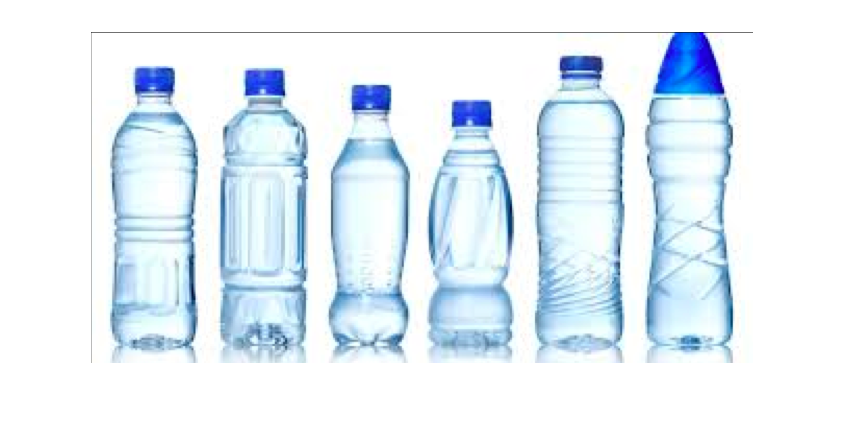

I = imread('images\Figure_Bottles.png');
gray_I = im2gray(I);
figure, imshow(I)

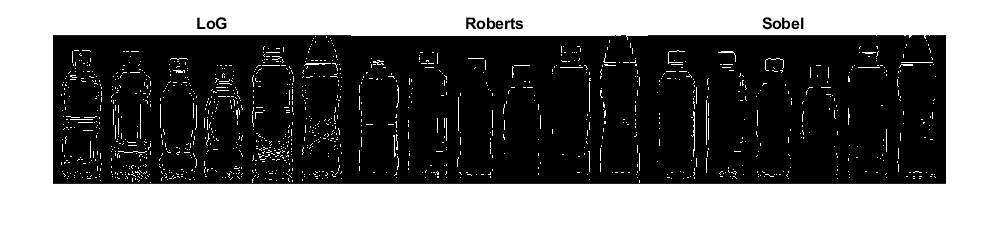

% Laplacian = fspecial('laplacian');
% I_L = imfilter(I,Laplacian);
I_L = edge(gray_I,'log');
I_R = edge(gray_I,'roberts');
I_S = edge(gray_I,'sobel');

% Displaying detections
figure, montage({I_L,I_R,I_S},'Size',[1 3])
title(['LoG                                                       ' ...
       'Roberts                                                       ' ...
       'Sobel'])

We can see on the image that Laplacian filter after Gaussian filter detects a lot of unnecessary edges. Filters like Roberts and Sobel are better with detecting only necessary edges and removing the noise. We can also see that Laplacian has only one pixel lines where the Roberts does not. Sobel has also one pixel contours, but sometimes can have more.

We tried to conect the contours applying certain mask but we did not obtained good results.

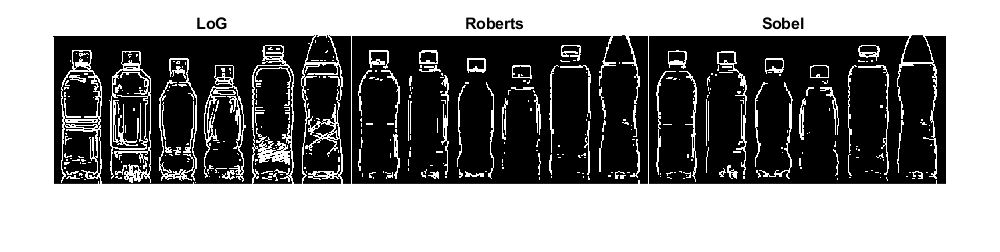

% Conecting contours using Mathematical morphology
mask = ones(3);
L_opt = imfilter(I_L,mask);
R_opt = imfilter(I_R,mask);
S_opt = imfilter(I_S,mask);

figure, montage({L_opt,R_opt,S_opt},'Size',[1 3])
title(['LoG                                                       ' ...
       'Roberts                                                       ' ...
       'Sobel'])

Using Mathematical morphology to extract contours.

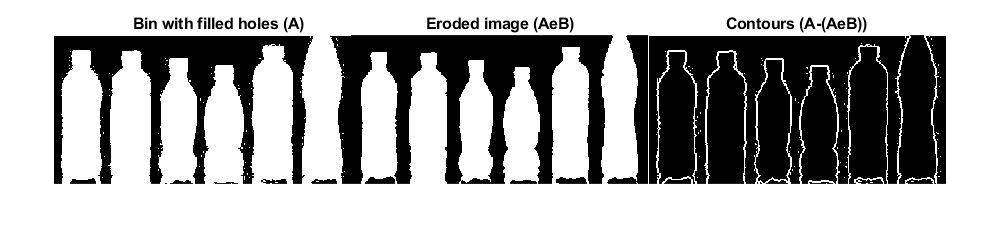

% Morphological operators
threshold = 248;
bin_I = gray_I<threshold;       % All pixels lower than threshold are 1
se1 = strel('disk', 4,0);       % Creating erosion mask
bin_I2 = imfill(bin_I,'holes'); % Filling holes in the image (A)
erod_I = imerode(bin_I2, se1);  % Creating erosion (AeB)
bound_I = bin_I2-erod_I;        % Getting the Contours from binary images (A-(AeB))

figure, montage({bin_I2,erod_I,bound_I},'Size',[1 3])
title(['Bin with filled holes (A)                            ' ...
       'Eroded image (AeB)                                   ' ...
       'Contours (A-(AeB))'])

We can see that, when using mathematical morphology we can create a lot better contours than using filters. These contours are ot one pixel lines.

- **2. For each one of the bottle contours, obtain the following features: perimeter, area, compacity, position of the bottles and orientation of the bottles.**

Obtaining features by *regionprops()* fuction where we put our eroded image.

blobMeasurements = regionprops(erod_I,'Perimeter','Area','Centroid','BoundingBox','Orientation')

blobMeasurements = 6×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    Orientation
    Perimeter


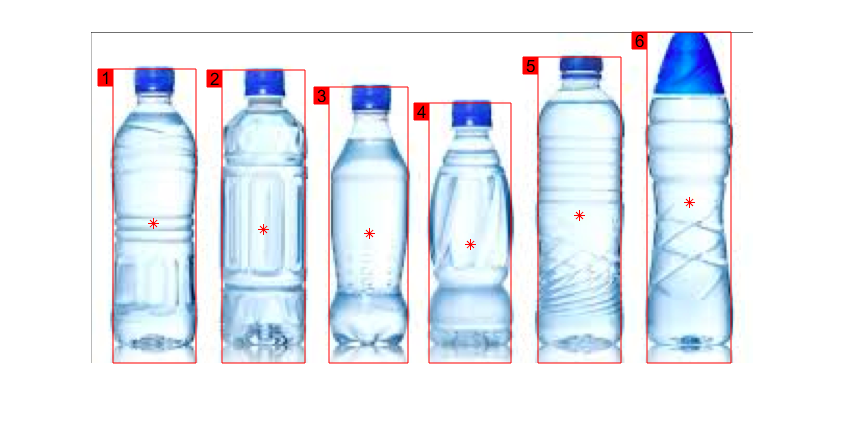

% Variables
P_all = [];     % Perimeter
A_all = [];     % Area
C_all = [];     % Centroid 
BB_all = [];    % Bounding Box

for i = 1:length(blobMeasurements)
    P_all(i) = blobMeasurements(i).Perimeter;
    A_all(i) = blobMeasurements(i).Area;
    C_all = [C_all;blobMeasurements(i).Centroid];
    BB_all = [BB_all;blobMeasurements(i).BoundingBox];
end

%% In case we find an object that is not a bottle this code will handle the problem
% Interval for only areas of the bottles
n = (A_all>10000).*(A_all<50000);

% Bottle Areas
A = (A_all.*n)';

% Bottle Perimeters
P = (P_all.*n)';

% Bottle Centroids
C = C_all.*n';
C(C==0) = [];
C = reshape(C,[6 2]);

% Bottle Bounding Boxes
BB = BB_all.*n';
BB(BB==0) = [];
BB = reshape(BB,[6 4]);

% Displaying results
figure, imshow(I), hold on,
for i = 1:size(BB,1)
    rectangle('Position',BB(i,:),'EdgeColor','r'),
    %text
    rectangle('Position',[BB(i,1)-15,BB(i,2),15,17],'FaceColor','r','EdgeColor','r'),
    text(BB(i,1)-12,BB(i,2)+8,num2str(i))
end
plot(C(:,1),C(:,2),'r*')
hold off

- **3. Using the features of point 2, can you identify univocally each one of the bottles?**

I think we can. We can use all the informations and when detecting another bottle we can use certain ratios between these features to detect which bottle it is.

## Exercise 3

- **Given the Fig.2 and Fig.3, which are the computer vision operations required to pass from the image of Fig.2 to Fig.3?**

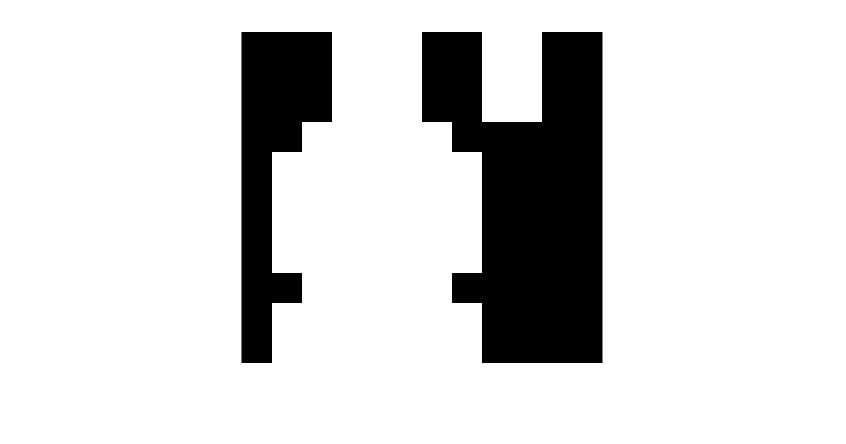

A = [0, 0, 0,70,70,70, 0, 0,70,70, 0, 0;
     0, 0, 0,70,70,70, 0, 0,70,70, 0, 0;
     0, 0, 0,70,70,70, 0, 0,70,70, 0, 0;
     0, 0,50,20,20,20,50, 0, 0, 0, 0, 0;
     0,50,20,20,20,40,20,50, 0, 0, 0, 0;
     0,50,20,20,40,20,20,50, 0, 0, 0, 0;
     0,50,20,40,20,20,20,50, 0, 0, 0, 0;
     0,50,40,20,20,20,20,50, 0, 0, 0, 0;
     0, 0,50,20,20,20,50, 0, 0, 0, 0, 0;
     0,50,20,20,20,20,20,50, 0, 0, 0, 0;
     0,50,50,50,50,50,50,50, 0, 0, 0, 0];

I = [0,0,1,1,1,1,0,0,0,0,0,0;
     0,0,1,0,0,1,0,0,0,0,0,0;
     0,1,1,0,0,1,0,0,0,0,0,0;
     0,1,0,0,0,0,1,0,0,0,0,0;
     1,1,0,0,0,0,1,1,0,0,0,0;
     1,0,0,0,0,0,0,1,0,0,0,0;
     1,1,0,0,0,0,1,1,0,0,0,0;
     0,1,0,0,0,0,1,0,0,0,0,0;
     0,1,0,0,0,0,1,0,0,0,0,0;
     0,1,1,0,0,1,1,0,0,0,0,0;
     0,0,1,1,1,1,0,0,0,0,0,0];


imshow(A)

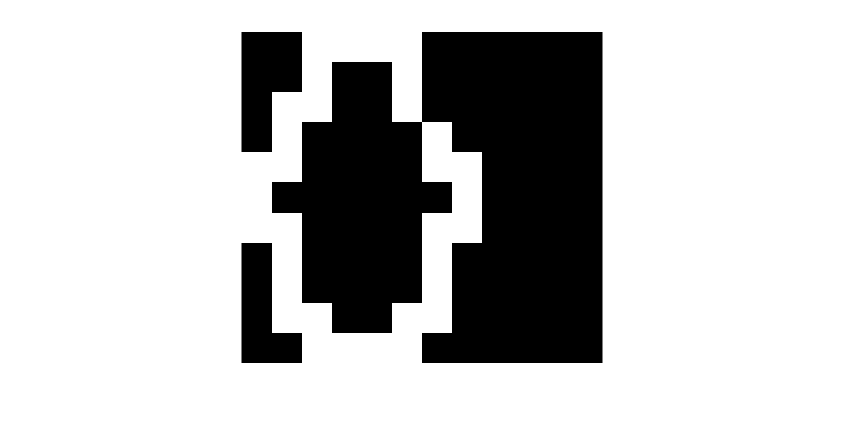

imshow(I)

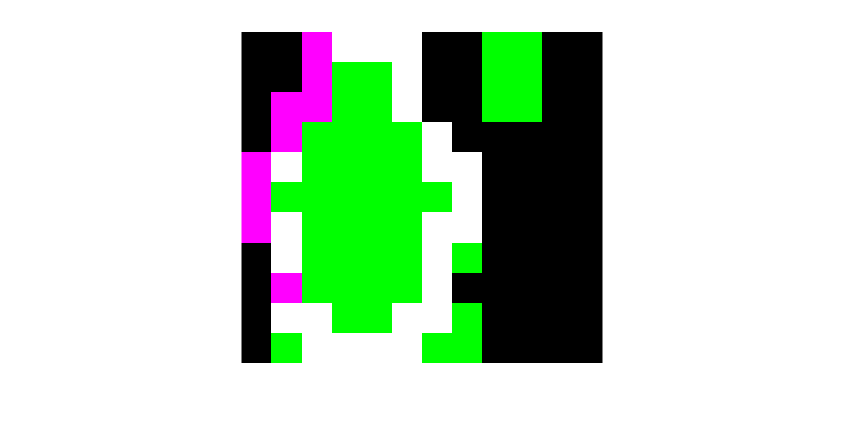


% Morphological operators
% threshold = 248;
bin_A = imbinarize(A); % All pixels lower than threshold are 1
% A(A>10)= 0;
A = im2gray(A);
% montage(imshow(A),imshow(I))
imshowpair(bin_A,I)

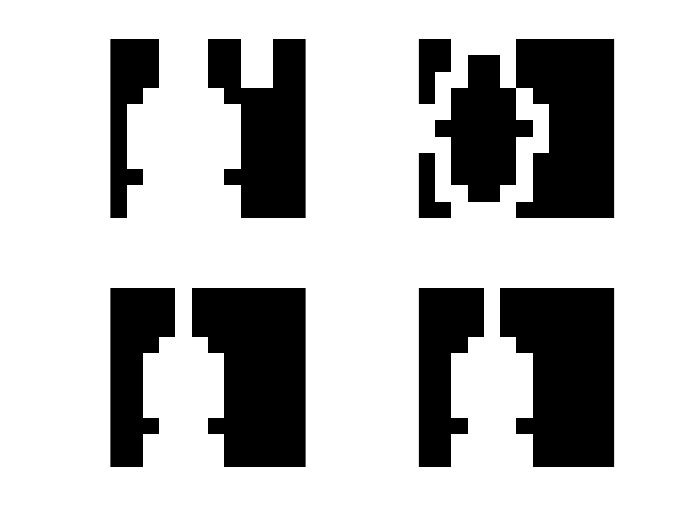

mask = [0 1 0;
        1 1 1;
        0 1 0];

E = imerode(bin_A,mask);
figure
subplot(2,2,1), imshow(A)
subplot(2,2,2), imshow(I)
subplot(2,2,3), imshow(E)
subplot(2,2,4), imshow(E)




% mask = [0   0   0   1   1   1   0   0   0   0   0   0
%         0   0   0   1   1   1   0   0   0   0   0   0
%         0   0   0   1   1   1   0   0   0   0   0   0
%         0   0   1   1   1   1   1   0   0   0   0   0
%         0   1   1   1   1   1   1   1   0   0   0   0
%         0   1   1   1   1   1   1   1   0   0   0   0
%         0   1   1   1   1   1   1   1   0   0   0   0
%         0   1   1   1   1   1   1   0   0   0   0   0
%         0   0   1   1   1   1   1   0   0   0   0   0
%         0   0   1   1   1   1   1   0   0   0   0   0
%         0   0   0   1   1   1   0   0   0   0   0   0];




% mask = [1 2 1;
%         0 0 0;
%         -1 -2 -1];
% I2 = imfilter(bin_I,mask');
% imshow(I2)




% se1 = strel('disk', 1,0);       % Creating erosion mask
% bin_I2 = imfill(bin_I,'holes'); % Filling holes in the image (A)
% erod_I = imerode(bin_I2, se1);  % Creating erosion (AeB)
% bound_I = bin_I2-erod_I;        % Getting the Contours from binary images (A-(AeB))
% 
% figure, montage({bin_I2,erod_I,bound_I},'Size',[1 3])
% title(['Bin with filled holes (A)                            ' ...
%        'Eroded image (AeB)                                   ' ...
%        'Contours (A-(AeB))'])
% E = [0 0 0 0 0 0 0 0 0 0 0;
%      0 0 0 0 0 0 0 0 0 1 1;
%      0 0 0 0 0 0 0 0 0 1 1;
%      0 0 0 0 0 0 0 0 0 1 1;
%      0 0 0 1 1 0 0 0 0 1 1];
% mask = [0 0 0;
%         0 1 0;
%         1 1 1];
% E1 = imerode(E,mask);
% E2 = imdilate(E,mask);
% imshow(E);
% imshow(E1);